# Try5 échoué version3 deux fois itérative 暂时放弃此版本

尝试不规则图形

Cf try3

Gauss-Seidel type matrice

version1: boucle for dans boucle while, pas de résultat

version2: echelon dans boucle while, pas de résultat

version3: deux fois itérative

## Paramètre


x=10;   %longueur en x
y=5;   %longueur en y
h=.1;  %pas
m=0:h:x;
n=0:h:y;
T=zeros(length(n),length(m));
Echelon=ones(length(n),length(m));
length(T)

ans = 101

## Condition frontière


T(1,:)=10;
T(:,1)=10;
T(length(n),:)=5;
T(:,length(m))=1;
for i=1:20
    for j=75:101
        Echelon(i,j)=0;
    end
end
T=T.*Echelon;
T1=T

T1 =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

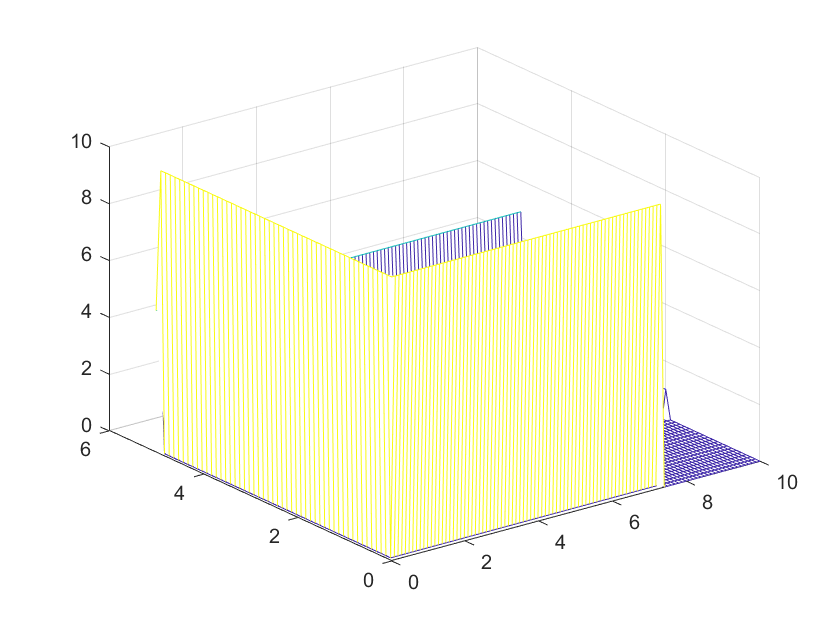

[xq,yq] = meshgrid(m, n);
mesh(xq,yq,T1)

## Gausse-Seidel 1

e=1; count=0;
while e>=0.001
    count=count+1;
    T1(2:length(n)-1,2:length(m)-1)=(T(2:length(n)-1,1:(length(m)-1)-1) ...%West
        +T(2:length(n)-1,3:(length(m)-1)+1) ...%East
        +T(1:(length(n)-1)-1,2:length(m)-1) ...%North
        +T(3:(length(n)-1)+1,2:length(m)-1))/4-(h^2*.2)/4; %South
    e=abs(max(max(T1-T)));
    T=T1;
end
count

count = 2028

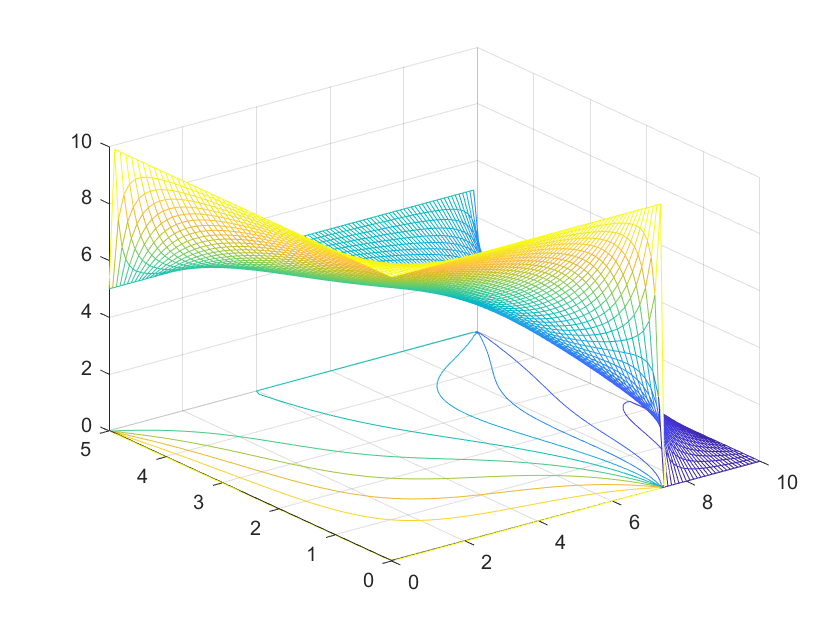


meshc(xq,yq,T)

# Version2 méthodes échelon, échoué, pas de résultat

## Paramètre

% 
% x=10;   %longueur en x
% y=5;   %longueur en y
% h=1;  %pas
% m=0:h:x;
% n=0:h:y;
% T=zeros(length(n),length(m));
% Echelon=ones(length(n),length(m));
% length(T)
% 

## Condition frontière

% 
% T(1,:)=10;
% T(:,1)=10;
% T(length(n),:)=5;
% T(:,length(m))=1;
% for i=1:3
%     for j=6:11
%         Echelon(i,j)=0;
%     end
% end
% Echelon
% T1=T
% [xq,yq] = meshgrid(m, n)
% mesh(xq,yq,T1)

## Gausse-Seidel

% e=1; count=0;
% while e>=0.001
%     count=count+1;
%     T=T.*Echelon;
%     T1(2:length(n)-1,2:length(m)-1)=(T(2:length(n)-1,1:length(m)-2) ...%West
%         +T(2:length(n)-1,3:length(m)) ...%East
%         +T(1:length(n)-2,2:length(m)-1) ...%North
%         +T(3:length(n),2:length(m)-1))/4-(h^2*.2)/4; %South
%     e=abs(max(max(T1-T)));
%     T=T1;
% end
% count
% 
% meshc(xq,yq,T)
